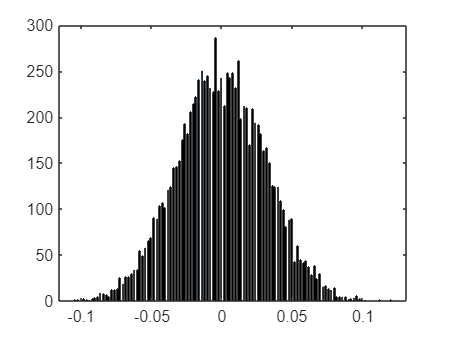

%To plot histogram of final location of 
% 10^5 random walks
% and find their mean and variance 
rng(0);
x=zeros(1, 10000);
mean=0;
var=0;
for i=1:10000
    coord=0;
    for j=1:1000
        ran=rand(1);
        if ran>=0.5
            coord=coord+0.001;
        else
            coord=coord-0.001;
        end
    end
    x(i)=coord;
    mean=mean+x(i)/10000;
    var=var+(x(i)^2)/10000;
end
histogram(x, 400);

mean

mean = 1.3860e-04

var

var = 9.9095e-04